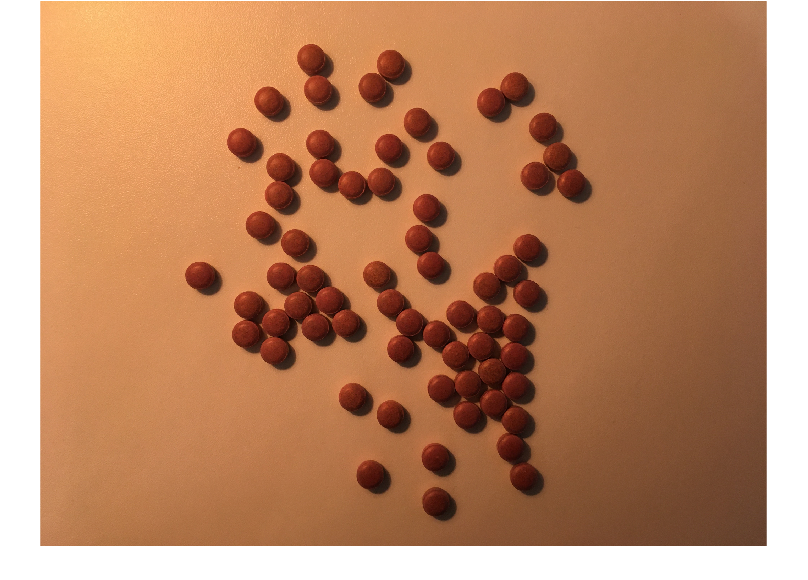

I = imread("pills_very_hard.jpg");
imshow(I);

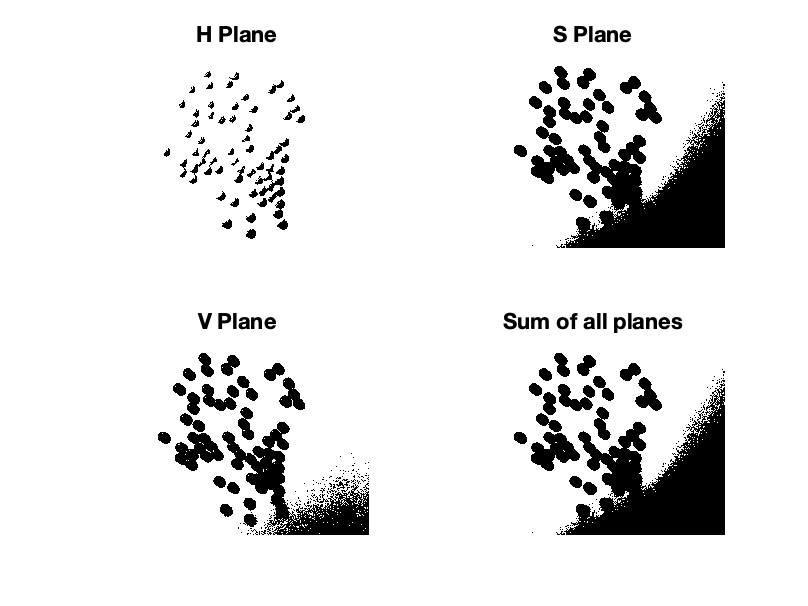

%%Solution: Thresholding the image
%Im=double(img/255)
Im=I;

%% RGB Colour space
hmat=Im(:,:,1);
smat=Im(:,:,2);
vmat=Im(:,:,3);

%%
levelh = 0.31;
levels = 0.4;
levelv = 0.2;
i1=imbinarize(hmat, levelh);
i2=imbinarize(smat, levels);
i3=imbinarize(vmat, levelv);
Isum = (i1&i2&i3);

figure;
subplot(2,2,1), imshow(i1);
title('H Plane')
subplot(2,2,2), imshow(i2);
title('S Plane')
subplot(2,2,3), imshow(i3);
title('V Plane')
subplot(2,2,4), imshow(Isum);
title('Sum of all planes')

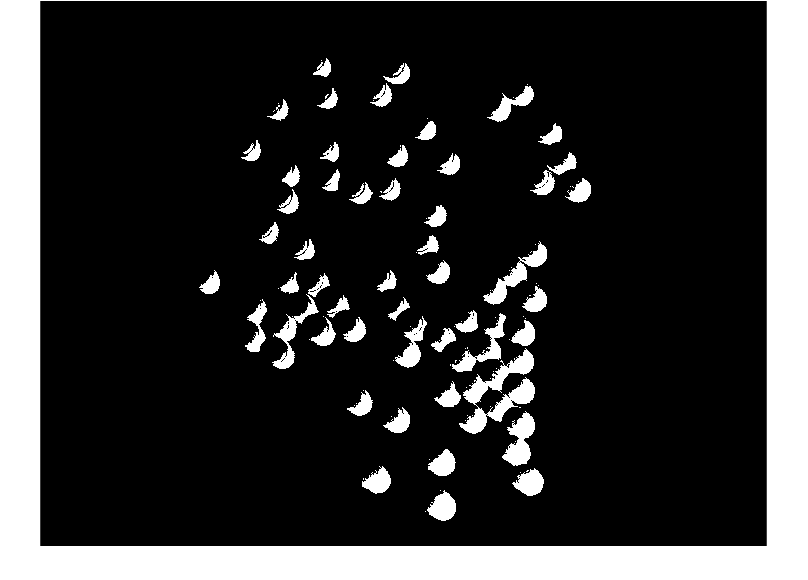


 %% Complement Image and Fill in holes
 Icomp = imcomplement(i1);
 Ifilled = imfill (Icomp,'holes');
 figure, imshow(Ifilled);

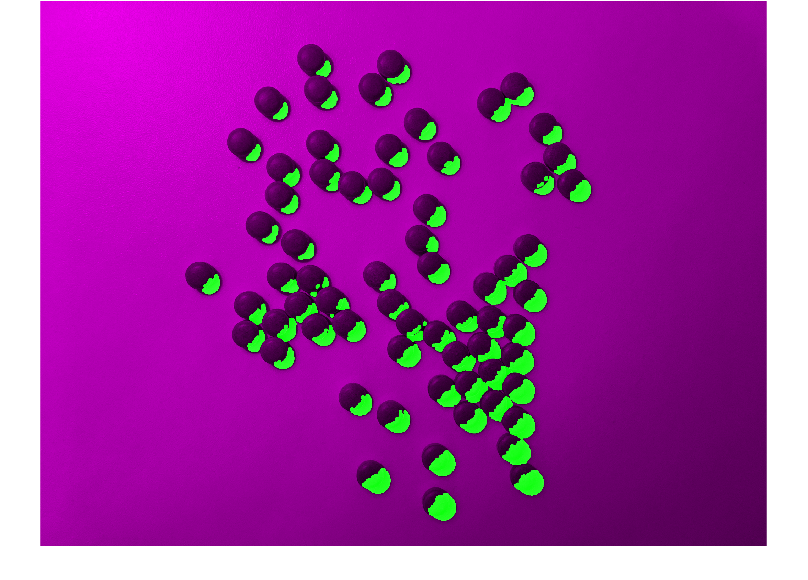


 %%
 se = strel('disk', 10);
 Iopenned = imopen(Ifilled,se);
 figure,imshowpair (Iopenned, I);

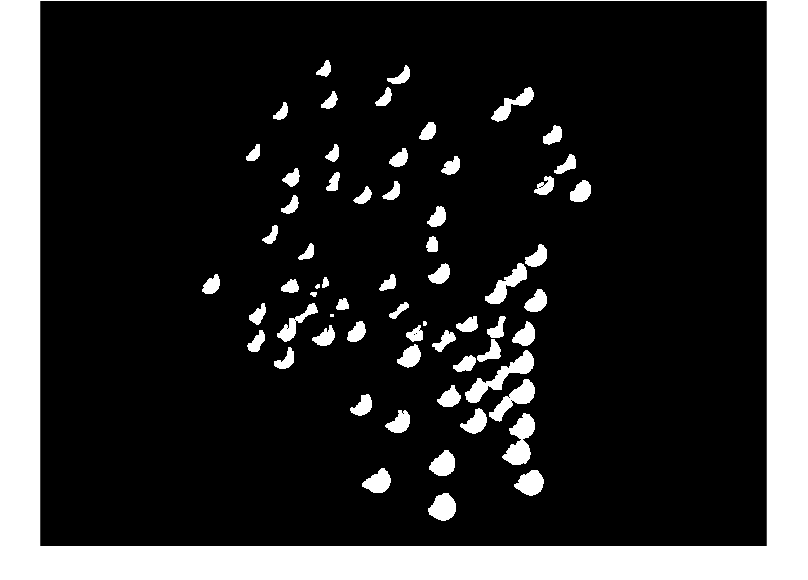

 imshow(Iopenned);

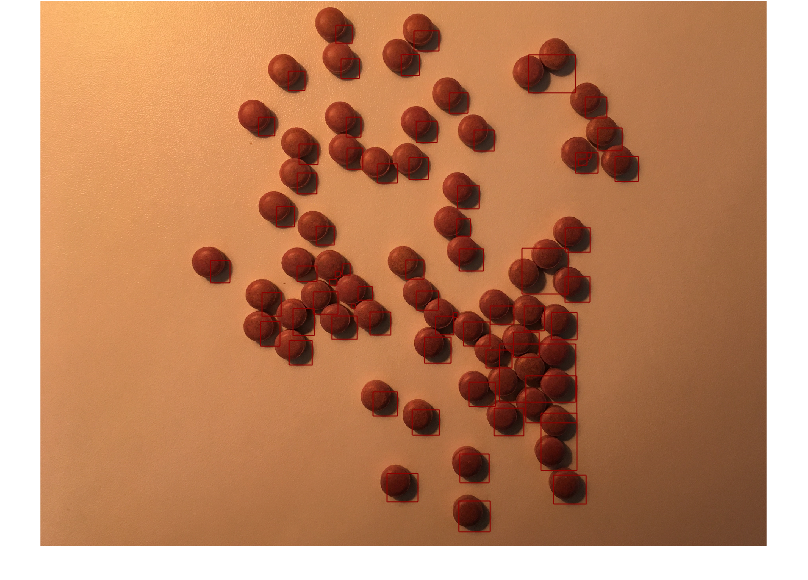

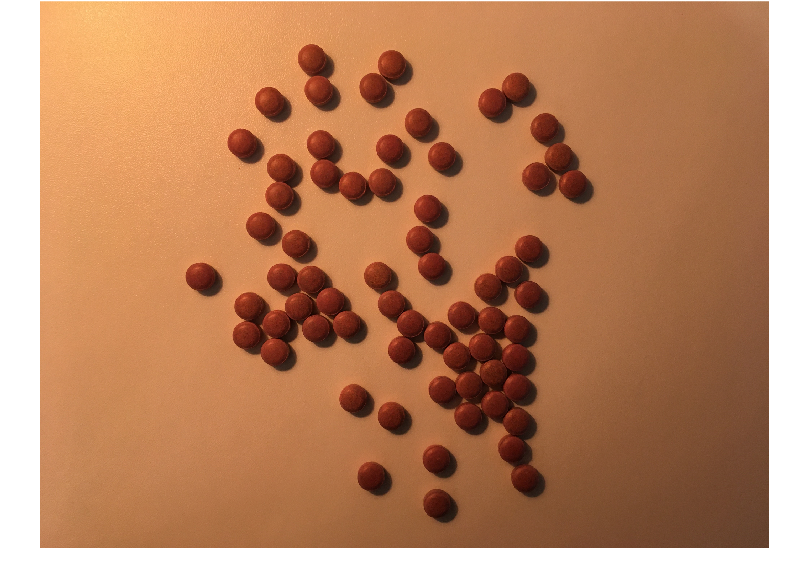


 %% Extract features

 Iregion = regionprops(Iopenned,'centroid');
 [labeled,numObjects] = bwlabel(Iopenned,4);
 stats = regionprops(labeled,'Eccentricity','Area','BoundingBox');
 areas = [stats.Area];
 eccentricities = [stats.Eccentricity];

 %% Use feature analysis to count pill objects
 idxOfPills = find(eccentricities);
 statsDefects = stats(idxOfPills);

 figure, imshow(I);
 hold on;
 for idx = 1 : length(idxOfPills)
     h = rectangle('Position', statsDefects(idx).BoundingBox);
     set(h,'EdgeColor',[.55 0 0]);
     hold on;
 end
 if idx > 10
 title(['There are ', num2str(numObjects), ' objects in the image!'])
 end
 hold off;